# Solve flat film ODE Model with Li et al evaporation, osmosis and flow

with time dependent extension rate (flow) inside tear film

1D thermal model with spectral method solution 

*Thermal IC is based on measured temp on eye surface*

*The Intensity decays from the start for this code.*

purpose to solve basic problem, no fitting yet, just guess and check

scalings based on trial's sample duration.

%close all;
clear all;

## Setup 1: Go to data directory

## Setup 2: trial independent parameters

dimensional parameters independent of trial

rho = 1e3;       % density of water, gm/liter
Pcdim = 12.1e-6; % m/s when e-6 is present (12.1 microns/s)
Vw = 18e-6;      % molar volume of water, m^3/mol
c0 = 300;        % serum osmolarity, mOsM or Osm/m^3, same thing; 300 ok too
sigma0 = 0.045;  % N/m
mu = 1.3e-3;     % Pa s
dc = 5e-4;       % corneal thickness in m
k = 0.68;        % TF conductivity, W/m/(deg K)
kc = 0.58;       % corneal conductivity, W/m/(deg K)
Lm = 2.3e6;      % latent heat of vap, J/kg
T_s = 20;        % saturation temp (guess); deg C
T_b = 37;        % body temp
T_inf = 25;      % room temp
kappa_c = 1.9e-7;  % corneal thermal diffusivity, m^2/s

% evaporative time scale in s; not used in fitting
% tau = d/v0;

% solute parameters
% fcr is critical concentation for max value in intensity at fixed d 
fcr = 0.002; % material property: critical FL concentration in mole frac
Mw_FL = 376; % molecular weight of Na_2FL, g/mol
% Naperian extinction coefficient
eps_f = 1.75e7;   % m^-1 M^-1
% transmittance parameter
fcr2 = rho*fcr/Mw_FL;  % convert fcr to Molar, then use eps_f

## Setup 3: trial specific

dimensional parameters from trials

These were exploratory values I used; see next section for things to try for comparison this time.

Input time for interval of fit, v0, a, b1, b2 as appropriate in dimensional values. These are base values to be changed below to explore where boundaries could be.

Test values

uncomment the block you want. p here is reminiscent of primed quantities to indicate that they are dimensional 

d = 7.6063e-6 - 1e-6;   % units: m
nnn = 421;             % number of images (assumes no drops)
ts = 0.05*(nnn-1);     % units: s
I_min = 11.7;          % floor of intensity
f0p = 0.10516*0.01;      % units: mol fraction (pct value*0.01, e.g.)
v0 = 10e-6/60;          % units: m/s
b1p = 0.04;            % units: 1/s
b2p = 0.04;            % units: 1/s
T_exp = 33.5;
hconv = 0.75e-3*k/d;    % convective heat transfer coefficient (9e-4 is Li et al)

## Setup 4: derived parameters

dimensional parameters computed for trials

f0p2 = f0p*rho/Mw_FL;             % initial concentration in M
capK = (T_b-T_s)/(rho*v0);        % gets initial v0 from temperatures

## Dimensionless parameters and solver tolerances

dimensionless extinction coefficient d*1e6 is microns; 1e-4 for cm -> microns

smphi = (eps_f)*fcr2*(d); 

% cornea related
%
% depth into eye for thermal problem
ytil_c = -5;  % 5 corneal thicknesses per Li et al
% corneal permeability (non dimnl) 
Pc = Pcdim*Vw*c0/(d/ts);  % units consistent here with mks
%
ktil = k/kc;           % conductivity ratio
dtil = d/dc;           % depth ratio
Pr = kappa_c*ts/dc^2;  % Prandtl number

% evap related
v = v0/(d/ts);
calL = Lm*(rho*d/ts)/( k*(T_b-T_s)/d );   % ratio of latent to conducted
Ktil = capK*(rho*d/ts)/(T_b-T_s);         % nondim K
Tinf = ( T_inf - T_s )/( T_b - T_s );     % nondim T_inf

% flow related
b1 = b1p*ts;          % nondim extension rate
b2 = b2p*ts;          % nondim decay rate
Bi = hconv*d/k;       % Biot number

% IC, etc
h0  = 1;  % IC when initial thickness is the 
f0 = f0p2/fcr2;

tspan = [0 1];

% nondimensionalize experimental temperatures
T_exp_nd = (T_exp-T_s)/(T_b-T_s);  

## PDE solving setup

% grid size, N+1 points
N = 64;

% Chebyshev definitions
[D1,yi] = cheb(N);
D2 = D1*D1;
% set up coordinate function
y = -(yi-1)*ytil_c/2;  % 0 to ytil_c
yfac = -2/ytil_c;

% compute weights for Clenshaw-Curtis integration
Nx = length(D1);
[junk,w] = clencurt(N);      % usual distribution

## IC setup

% initial values
y0 = ones(Nx+3,1);      % incl h, c, Tc
y0(3,1) = f0;           % flourescein concentration (frac of crit)
T_00 = T_exp_nd(1)*(1+Bi+calL/Ktil)-Bi*Tinf;   % corneal surface temp in theory
T_init = T_00 + (1-T_00)*(y/ytil_c);
y0(4:Nx+3,1) = T_init;

## Define ODE rhs's and solve

% tolerances
MyTols = odeset('RelTol',2e-6,'AbsTol',1e-6,'Mass',@ODEThermMass,...
        'MassSingular','yes');
% solve ODEs -- Model D plus thermal equations from Li et al 2012
[T,Y] = ode15s(@(t,u) ode_therm(t,u,Pc,b1,b2,yfac,D1,D2,Tinf,Pr,...
                                calL,ktil,dtil,Bi,Ktil),...
               tspan,y0,MyTols);

% readable form
N = N+1;
t = T;
h = Y(:,1); c = Y(:,2); f = Y(:,3); T_c = Y(:,4:N+3);

## Post processing

T_0 = Y(:,4);     % TF/cornea interface temp
T_h = ( T_0 + Bi*h*Tinf )./( 1 + ( Bi + calL/Ktil )*h ); % TF surface temp
Je = ( T_0 + Tinf*Bi*h)./( Ktil*( 1+Bi*h ) + calL*h );   % evap rate
% T_exp_nd = (T_exp - T_s)/( T_b - T_s );

% integral of strain rate for flow
gint = exp( (b1/b2)*( exp(-b2*t)-1) );   % with f0, gives hf
% compute intensity
glo = ( 1 - exp(-smphi*f0*gint) )./(1+ ( (f0*gint)./h ).^2);
glo = glo/glo(1);

## Plot dimensionless solutions

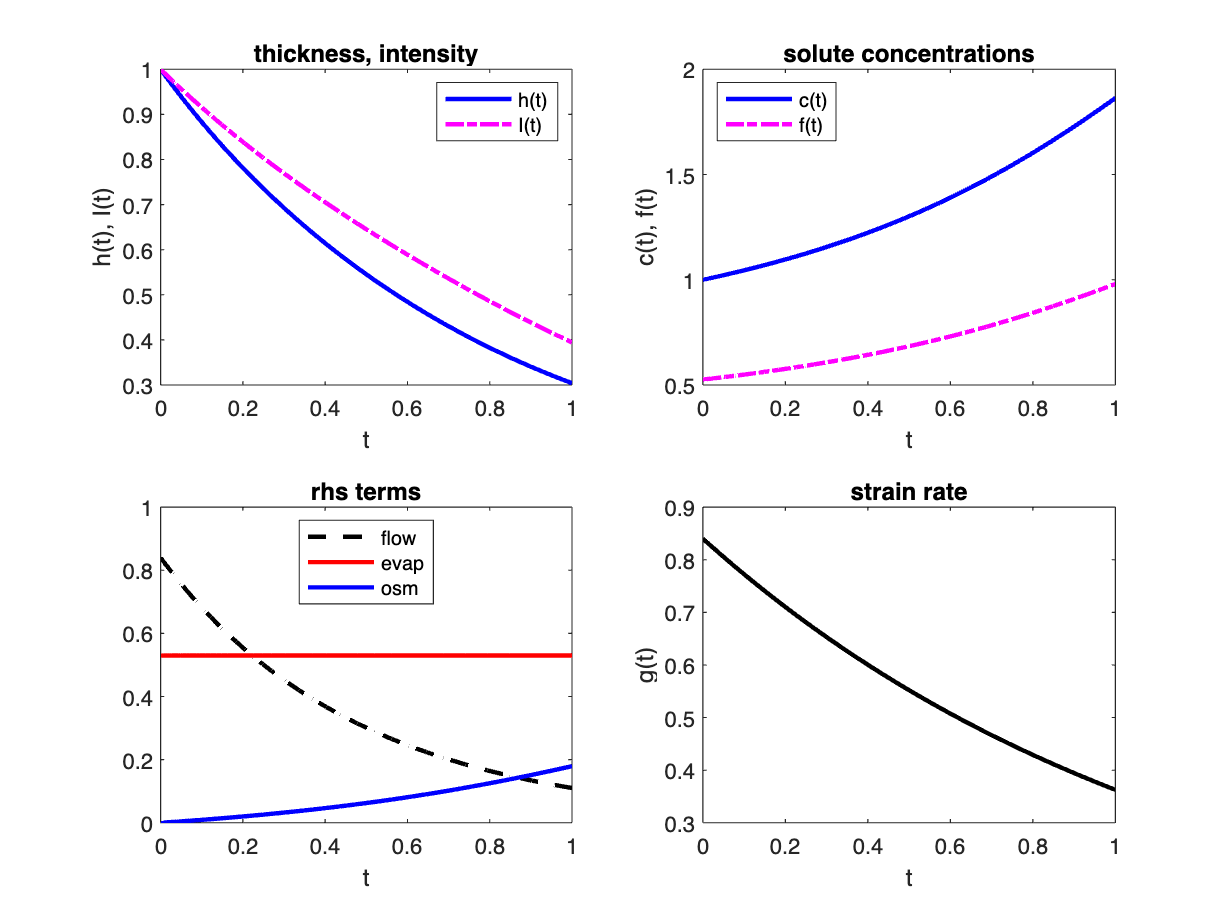

%Plot thickness, intensity, etc
figure
subplot(2,2,1)
plot(t,h,'b-','LineWidth',2)
hold on
plot(t,glo,'m-.','LineWidth',2)
hold off
ylabel('h(t), I(t)')
xlabel('t')
title('thickness, intensity')
legend('h(t)','I(t)','Location','NorthEast')

% Plot solute concentrations
% figure
subplot(2,2,2)
c = gint./h;   % uses mass conservation equation
f = f0*gint./h;
plot(t,c,'b-',t,f,'m-.','LineWidth',2)
ylabel('c(t), f(t)')
xlabel('t')
title('solute concentrations')
legend('c(t)','f(t)','Location','NorthWest')

% Plot strain rate
g = b1*exp( -b2*t );
subplot(2,2,4)
plot(t,g,'k-','LineWidth',2)
ylabel('g(t)')
xlabel('t')
title('strain rate')

% Plot each term of the ODE rhs
% plotting the rhs terms over time in the same plot
subplot(2,2,3)
flow = g.*h;
evap = v*ones(size(h));
osm = Pc*(gint./h - 1);
plot(t,flow,'k--',t,evap,'r-',t,osm,'b-','LineWidth',2)
xlabel('t')
title('rhs terms')
legend('flow','evap','osm','Location','north')
hold off

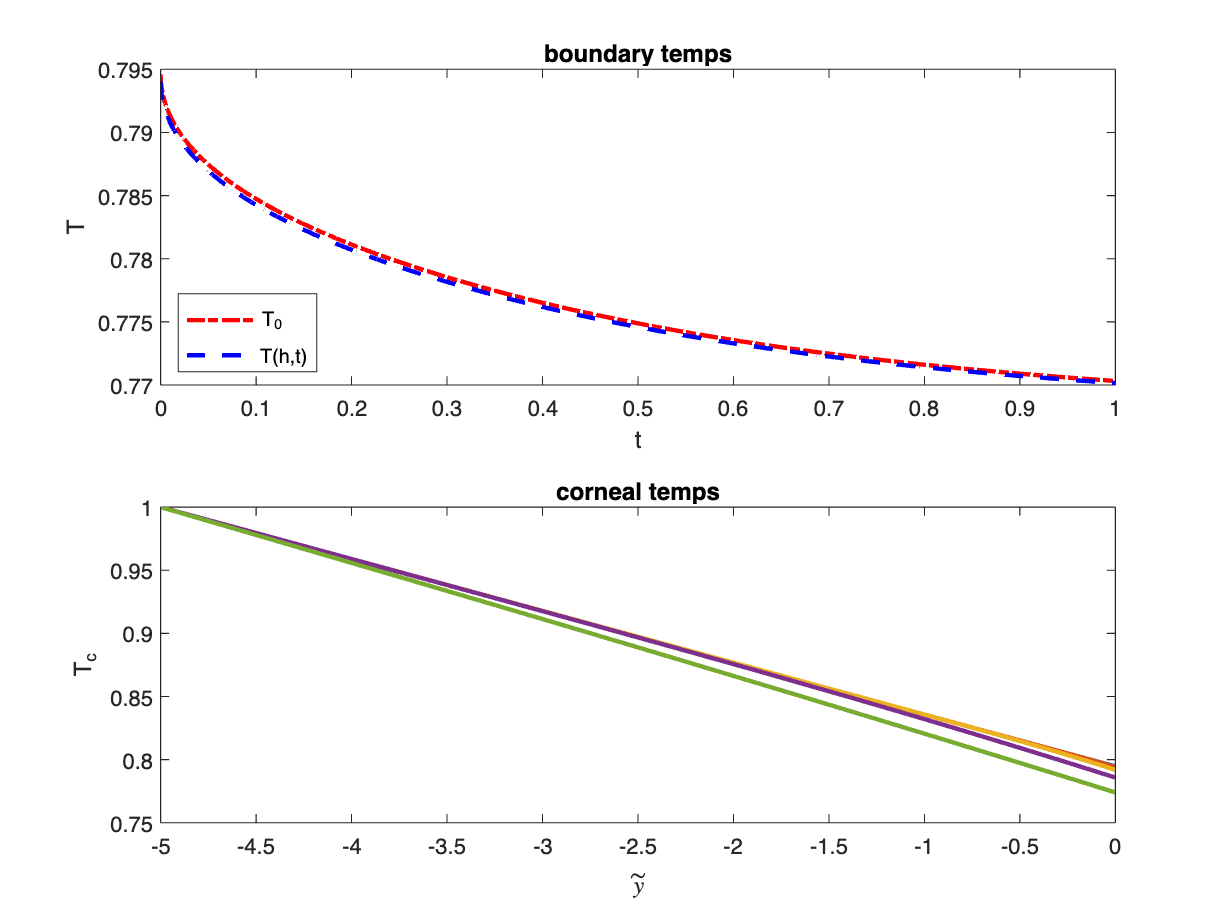


% Plot thermal field in cornea
figure
subplot(2,1,1)
plot(t,T_0,'r-.',t,T_h,'b--','LineWidth',2)
xlabel('t'), ylabel('T'), title('boundary temps')
legend('T_0','T(h,t)','Location','SouthWest')
subplot(2,1,2)
% plot(y,fliplr(T_c(1:20:end,:)),'LineWidth',2)
plot(y,T_c(1:20:end,:),'LineWidth',2)
xlabel('$\tilde{y}$','Interpreter','LaTeX'), ylabel('T_c'), title('corneal temps')

## Plot dimensional solutions (i.e., with units)

undo scalings:

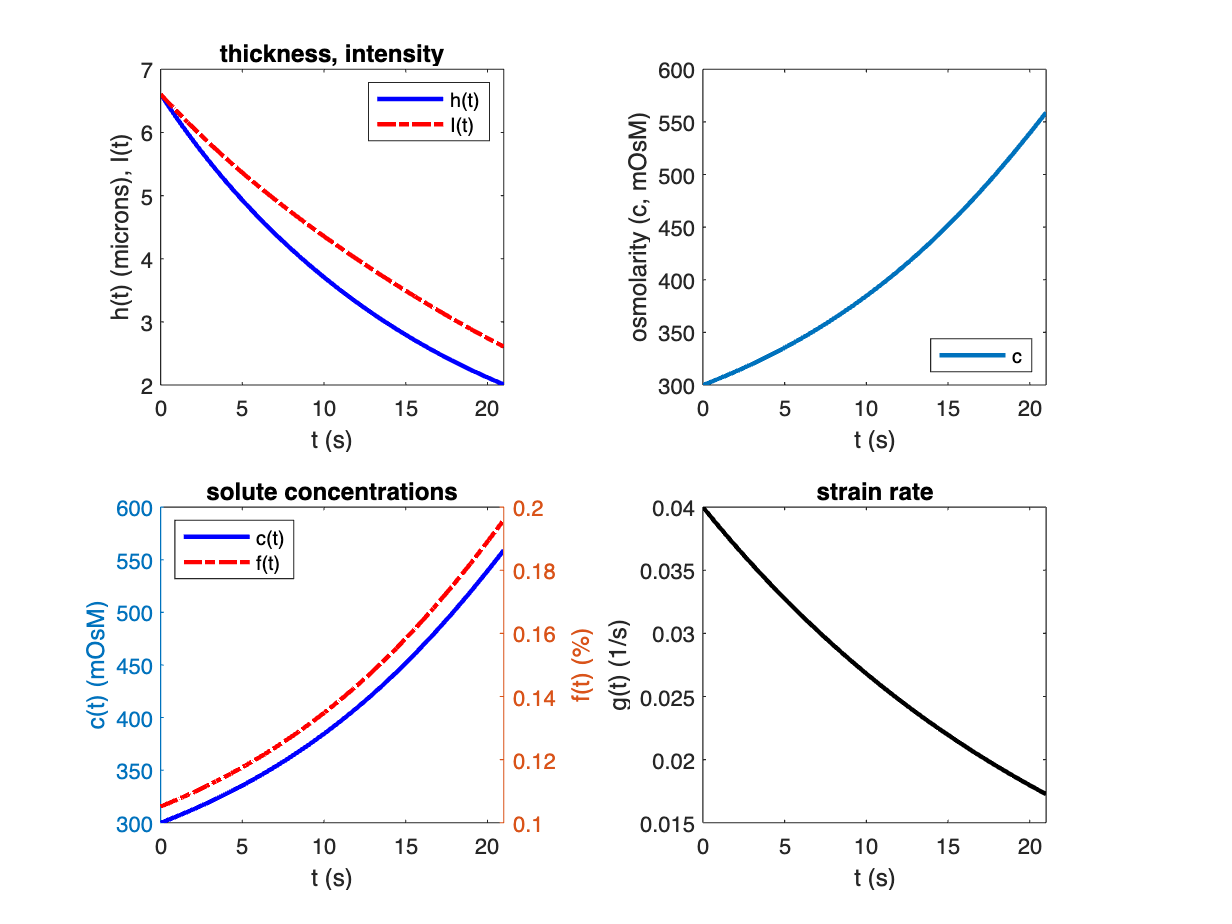

tt = ts*t;            % units in s again
hh = d*h;             % units in m again
gloglo = d*glo;       % (normalized to start with initial thickness)
cc = c0*c;            % units in mOsM again
ff = f0p*f;           % units in mol frac again
gg = g/ts;            % units in 1/s again (strain rate)
vv = v*d/ts;          % units in m/s again
T_h_dim = T_h*(T_b-T_s)+T_s;  % units in C
T_0_dim = T_0*(T_b-T_s)+T_s;  % units in C
T_c_dim = T_c*(T_b-T_s)+T_s;    % units in C

% Plot thickness, intensity.  
figure
%title('no flow, a=0')
subplot(2,2,1)
plot(tt,hh*1e6,'b-','LineWidth',2)
hold on
plot(tt,gloglo*1e6,'r-.','LineWidth',2)
hold off
ylabel('h(t) (microns), I(t)')
xlabel('t (s)')
title('thickness, intensity')
legend('h(t)','I(t)','Location','NorthEast')

% Plot solute concentrations
subplot(2,2,3)
yyaxis left
plot(tt,cc,'b-','LineWidth',2)
xlabel('t (s)')
ylabel('c(t) (mOsM)') % left y-axis 
yyaxis right
plot(tt,ff*100*f0p/ff(1),'r-.','LineWidth',2)
ylabel('f(t) (%)') % right y-axis
title('solute concentrations')
legend('c(t)','f(t)','Location','NorthWest')

% Plot strain rate
subplot(2,2,4)
plot(tt,gg,'k-','LineWidth',2)
ylabel('g(t) (1/s)')
xlabel('t (s)')
title('strain rate')

% Plot each term of the ODE rhs in the same plot
subplot(2,2,2)
plot(tt,cc,'LineWidth',2)
xlabel('t (s)'), ylabel('osmolarity (c, mOsM)')
legend('c','Location','Southeast')

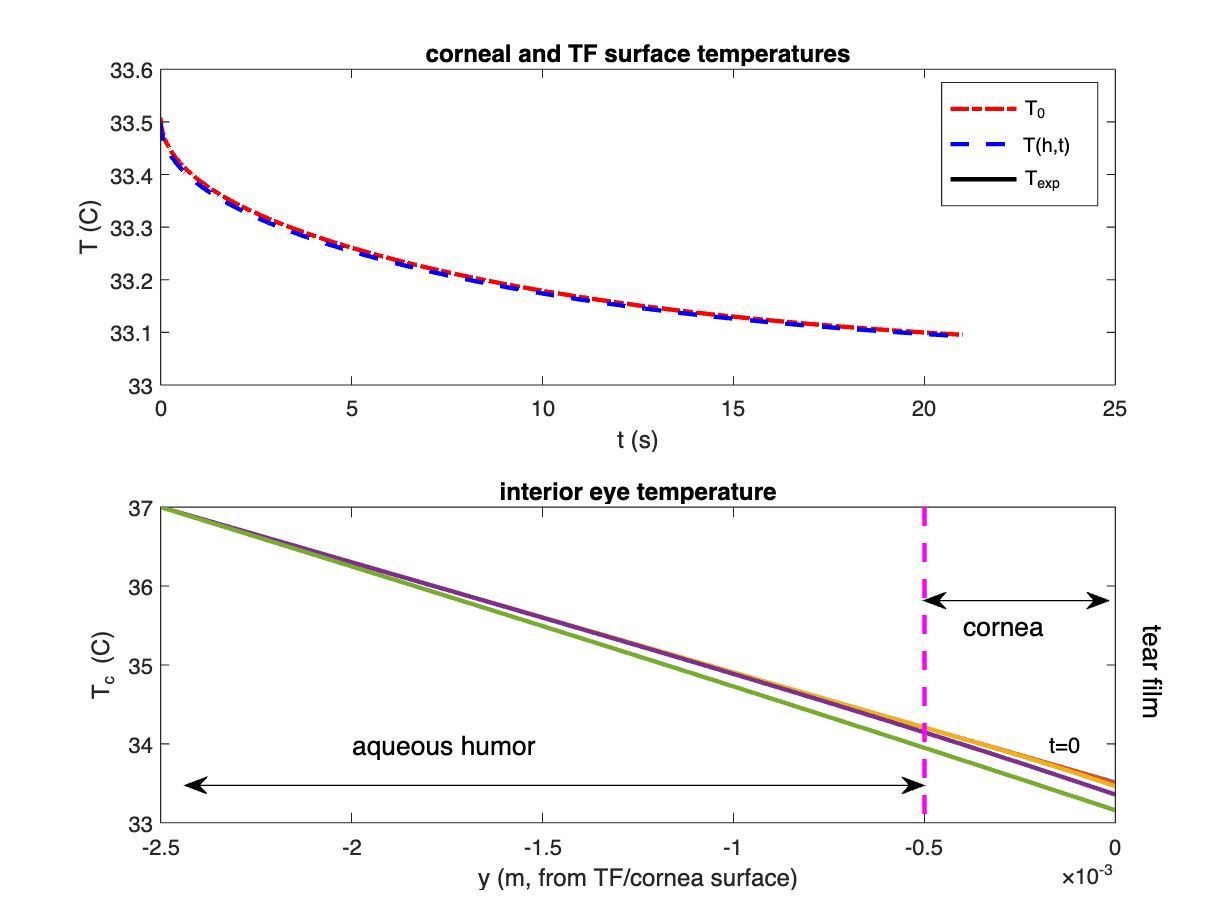

% Plot thermal field in cornea
figure
subplot(2,1,1)
plot(tt,T_0_dim,'r-.',tt,T_h_dim,'b--',tt,T_exp,'k-','LineWidth',2)
xlabel('t (s)'), ylabel('T (C)'), title('corneal and TF surface temperatures')
legend('T_0','T(h,t)','T_{exp}','Location','NorthEast')
subplot(2,1,2)
plot(dc*y,T_c_dim(1:20:end,:),'LineWidth',2)
hold on
plot([-1 -1]*dc,[max(max(T_c_dim)) min(min(T_c_dim))],'m--','LineWidth',2)
text(-0.8*dc,35.5,'cornea','FontSize',12)
ttt = text(0.2*dc,35.5,'tear film','FontSize',12);
ttt.Rotation = -90;
text(-0.35*dc,34.0,'t=0')
annotation('doublearrow',[0.75 0.9],[0.35 0.35])
text(-4*dc,34,'aqueous humor','FontSize',12)
annotation('doublearrow',[0.15 0.75],[0.15 0.15])
xlabel('y (m, from TF/cornea surface)'), ylabel('T_c (C)')
title('interior eye temperature'), hold off

#### Function used

function f = ode_therm(t,u,Pc,b1,b2,yfac,D1,D2,Tinf,Pr,calL,ktil,dtil,Bi,Ktil)
% [T,Y] = ode15s(@(t,u) ode_therm(t,u,Pc,b1,b2,yfac,D1,D2,Tinf,Pr,calL,ktil,dtil,Bi,Ktil),tspan,y0,MyTols);
% function for Longfei's thermal model together with Rayanne's scaled TF
% ODEs for (eventually) fitting
% Neumann conditions at TF for thermal, Dirichlet away from TF
% called by Evap1LayOsmo_NLplanar12.m
% input:  t  (scalar, not always used)
%         u  row vector of h, c, f and Tc (temperature)
% output: f rhs of f  (column vector)

N = length(D1);

% readable variables 
h = u(1,1);           % thickness
c = u(2,1);           % osmolarity
fl = u(3,1);          % fluorescein concentration
Tc = u(4:N+3,1);      % corneal temperature
Tc_y = yfac*D1*Tc; Tc_yy = yfac^2*D2*Tc;   % temperature derivatives
T0 = Tc(1);           % TF/cornea boundary temp
Th = ( T0 + Bi*h*Tinf )/( 1 + ( Bi + calL/Ktil )*h ); % TF surface temp

% evaporation rate expression
Je = ( T0 + Tinf*Bi*h)/( Ktil*( 1+Bi*h ) + calL*h ); 

% flow parameter 
g = b1*exp( -b2*t );

% tear film quantities
rhs    =  Je - Pc*(c-1);
f(1,1) = - rhs - g*h;     % thickness
f(2,1) = c*rhs/h;           % osmolarity
f(3,1) = fl*rhs/h;          % fluorescein concentration

% temperature
f(N+3,1)   = Tc(end)-1;                % Dirichlet BC inside eye
f(5:N+2,1) = Pr*Tc_yy(2:end-1,1);    % diffusion inside eye
% Neumann BC for temperature at TF/Cornea interface:
f(4,1)     = Tc_y(1) + (ktil/dtil)*( calL*Je + Bi*(Th-Tinf) );    

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function M = ODEThermMass(t,y)
% Neumann one end of cornea, Dirichlet on the other
% 3 ODE: h, c, f; 1 PDE: Tc

N=length(y);  N = N - 3;
M=speye(N+3);
M(4,4) = 0;
M(end,end) = 0; 

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [D,x] = cheb(N)
%  function [D,x] = cheb(N)
% compute Chebyshev spectral differentiation matrices 
% Input
%    N = number of grid points minus one
% Output
%    D = differentiation matrix 
%    x = Chebyshev grid

if N==0, D=0; x=1; return, end
x = cos(pi*(0:N)/N)';
c = [2; ones(N-1,1); 2].*(-1).^(0:N)';
X = repmat(x,1,N+1);
dX = X-X';
D = (c*(1./c)')./(dX+(eye(N+1)));     % off-diagonal entries
D = D - diag(sum(D'));                % diagonal entries

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x,w] = clencurt(N)
% clencurt  nodes x (Chebyshev points) and weights w
%           for Clenshaw-Curtis quadrature
 theta = pi*(0:N)'/N; x = cos(theta);
 w = zeros(1,N+1); ii = 2:N; v = ones(N-1,1);
 if mod(N,2)==0
    w(1) = 1/(N^2-1); w(N+1) = w(1);
    for k=1:N/2-1
        v = v - 2*cos(2*k*theta(ii))/(4*k^2-1); 
    end
    v = v - cos(N*theta(ii))/(N^2-1);
 else
    w(1) = 1/N^2; w(N+1) = w(1);
    for k=1:(N-1)/2
        v = v - 2*cos(2*k*theta(ii))/(4*k^2-1); 
    end
 end
 w(ii) = 2*v/N;
end